# **Opgave 1: Sandsynlighedsregning**

**Røgalarmer skal være så følsomme, at man er ret sikker på, at de giver alarm, når der er røg-udvikling i lokalet. Ulempen ved dette er, at de også nogle gange giver alarm selvom, der ikke er røgudvikling.**

**For at undersøge pålideligheden af en ny type røgalarmer laves en omfattende, kontrolleret test-undersøgelse med situationer med og uden røgudvikling. Der var røgudvikling i 1/3 af testsitua-tionerne. Resultatet af denne undersøgelse viser, at i 32% af situationerne var der både røg-udvikling og alarm, mens der i 7% af situationerne var alarm, selvom der ikke var røgudvikling.**


$$\begin{array}{l}
A=\textrm{Alarm}\\
\bar{\;A} =\textrm{ingen}\;\textrm{Alarm}\\
R=\textrm{R\og}\\
\bar{\;R} =\textrm{ingen}\;\textrm{R\og}
\end{array}$$



$$\begin{array}{l}
\Pr \left(R\right)=0\ldotp 333\\
\Pr \left(\bar{\;R} \right)=1-0\ldotp 333=0\ldotp 666\\
\Pr \left(R\cap A\right)=0\ldotp 32\\
\Pr \left(\bar{\;R} \cap A\right)=0\ldotp 07
\end{array}$$


**a) I hvor stor en del af situationerne var der alarm?**

**Vi kan tage sandsynligheden for at alarmen lyder med røg og sandsynligheden for at alarmen tyger uden røg og læggge dem sammen for at få den fulde sandsynlighed**


$$\begin{array}{l}
\Pr \left(A\right)=\Pr \left(R\cap A\right)+\Pr \left(\bar{\;R} \cap A\right)=0\ldotp 32+0\ldotp 07=0\ldotp 39\\
\Pr \left(\bar{\;A} \right)=1-0\ldotp 39=0\ldotp 61
\end{array}$$


*39% af situationerne var der alarm*

**b) Hvad er sandsynligheden for, at i situationer uden røgudvikling, vil der alligevel være alarm?**


$$\Pr \left(\bar{\;R} \left|A\right.\right)=\frac{\Pr \left(\bar{\;R} \cap A\right)}{\Pr \left(A\right)}=\frac{0\ldotp 07}{0\ldotp 39}=0\ldotp 1795$$



$$\Pr \left(A\left|\bar{\;R} \right.\right)=\frac{\Pr \left(\bar{\;R} \left|A\right.\right)\cdot \Pr \left(A\right)}{\Pr \left(\bar{\;R} \right)}=\frac{0\ldotp 1795\cdot 0\ldotp 39}{0\ldotp 666}=0\ldotp 1051$$



$$\Pr \left(A\cap \bar{\;R} \right)=\Pr \left(A\left|\bar{\;R} \right.\right)\cdot \Pr \left(\bar{\;R} \right)=0\ldotp 1051\cdot 0\ldotp 666=0\ldotp 07$$


*Sandsynligheden for at alarmen lyder uden røg er 10.5%*

**c) Hvad er sandsynligheden for, at der ikke er alarm i situationer med røgudvikling.**


$$\Pr \left(\bar{\;A} \left|R\right.\right)=1-\Pr \left(A\left|R\right.\right)=1-\frac{\Pr \left(A\cap R\right)}{\Pr \left(R\right)}=1-\frac{0\ldotp 32}{0\ldotp 333}=0\ldotp 0390$$


*Der er 4% sandsynlighed for at alarmen lyder uden røgudvikling*

# Opgave 2: Stokastiske Variable

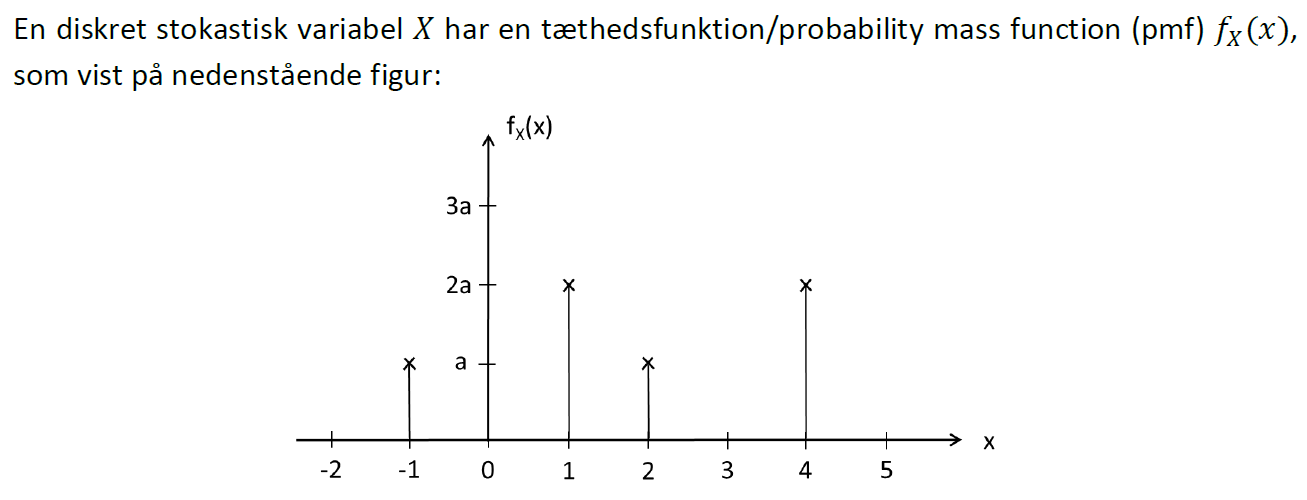

**a) Bestem a, så fx(x) er en gyldig tæthedsfunktion/probability mass function (pmf).**

syms a;
a=solve(a+2*a+a+2*a==1)

$$a = \frac{1}{6}$$

*a er *$\frac{1}{6}$

**b) Bestem og skitsér fordelingsfunktionen FX(x) for den stokastiske variabel X.**

**vi ved at a er 1/6**


$$\textrm{fx}\left(x\right)\left\lbrace \left\lbrack \begin{array}{cc}
\frac{1}{6} & ,\;x\le -1\\
2\cdot \frac{1}{6} & ,-1\le x<1\\
\frac{1}{6} & ,1\;\le x<2\\
2\cdot \frac{1}{6} & ,2\le \;x<4\\
1 & ,\;4\le x
\end{array}\right\rbrack \right\rbrace$$


**vi starter af med at sætte grænser op. **


$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=0\;,\textrm{for}\;x<\;-1$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=1\;,\textrm{for}\;x\ge 4$$


herefter kan vi finde cdf for grænserne


$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=-1\right)=\frac{1}{6}\;,\textrm{for}\;-1\le x<1$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=-1\right)+P\left(X=1\right)=\frac{1}{6}+\left(2\cdot \;\frac{1}{6}\right)=\frac{1}{6}+\frac{2}{6}=\frac{1}{2},\textrm{for}\;1\le x<2$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=-1\right)+P\left(X=1\right)+P\left(X=2\right)=\frac{1}{6}+\frac{2}{6}+\frac{1}{6}=\frac{4}{6}=\frac{2}{3},\textrm{for}\;2\le x<4$$



$$\textrm{Fx}\left(x\right)=P\left(X\le x\right)=P\left(X=-1\right)+P\left(X=1\right)+P\left(X=2\right)+P\left(X=4\right)=\frac{1}{6}+\frac{2}{6}+\frac{1}{6}+\frac{2}{6}=\frac{6}{6}=1,\textrm{for}\;x\ge 4$$



$$f_x(x) = \left\{ 
\matrix{
0 & , for & x < -1 \cr
\frac16 & , for & -1 <= x < 1 \cr
\frac12 & , for & 1 <= x < 2 \cr
\frac23 & , for & 2 <= x < 4 \cr
1 & , for & x >= 4 \cr
}$$


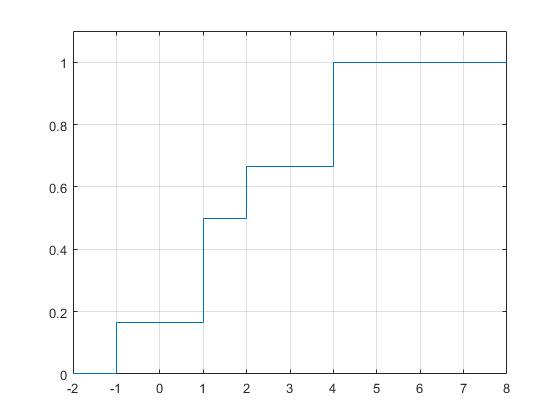

x=[-2 -1 1 2 4 8]; % udvidelsen med -2 og 8 er bare for at vise at den ikke ændre sig.
Fx=[0 1/6 1/2 2/3 1 1]; % udvidelsen med 0 og 1 er bare for at vise at den ikke ændre sig.
figure;
stairs(x,Fx);
set(gca, 'xlim', [0 8]);
grid
xlim([-2.0 8.0])
ylim([0.000 1.1])

**c) Opstil udtrykket for og find middelværdien af X.**

**middelværdi:**


$$E\left\lbrack X\right\rbrack \sum_x x\cdot \;\textrm{fx}\left(x\right)=-1\cdot \frac{1}{6}+1\cdot \frac{2}{6}+2\cdot \frac{1}{6}+4\cdot \frac{2}{6}=1\ldotp 833$$


**Middelværdi er 1.833**

**d) Opstil udtrykket for og find variansen af X.**

**varians:**


$$E\left\lbrack X^2 \right\rbrack \sum_x x^2 \cdot \;\textrm{fx}\left(x\right)=-1^2 \cdot \frac{1}{6}+1^2 \cdot \frac{2}{6}+2^2 \cdot \frac{1}{6}+4^2 \cdot \frac{2}{6}=6\ldotp 50$$



$$\textrm{Var}\left(x\right)=$$

$$E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 =6\ldotp 50-1\ldotp {833}^2 =6\ldotp 50-3\ldotp 36=3\ldotp 14$$


***variansen er 3.14***

# Opgave 3: Stokastiske Processer

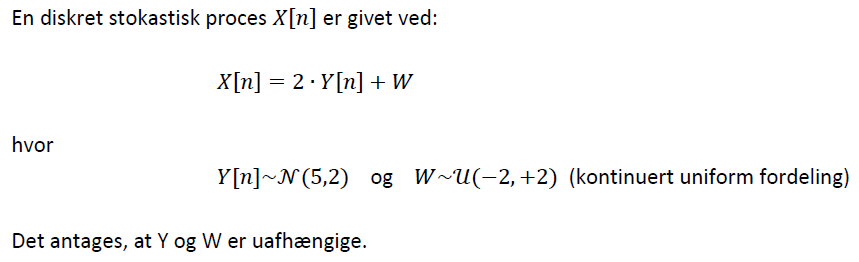

**a) Skitser 11 samples (n=0,…,10) af en realisation af den stokastiske proces X[n]. Angiv hvordan processen er simuleret (brug en tilfældighedsgenerator, f.eks. randn() og rand() i Matlab).**

%One realization 11 samples
Wa = -2;
Wb = 2;
W=(2-(-2))*rand(1,11)-2;

YnSigma=2;
YnMu=5;
Yn=randn(1,11)*sqrt(YnSigma)+YnMu;

Xn=2*Yn+W

Xn =     7.3590    9.6079    9.8150   12.2817    7.5206   11.3762    5.8921    5.2640   10.2100    9.1626   12.0176


    TidsligMiddel = sum(Xn)/11

TidsligMiddel = 9.1370

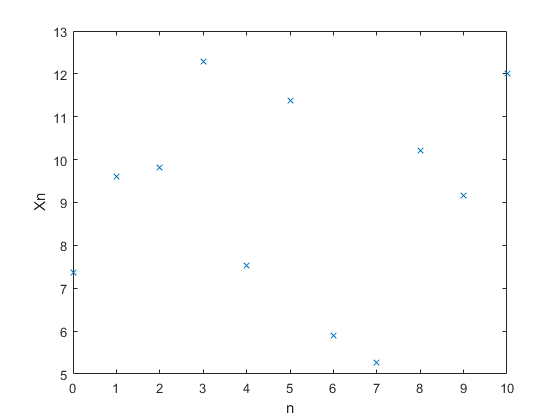

    figure;
    plot(0:10,Xn,'x')
    xlabel('n')
    ylabel('Xn')

*Processen er simuleret ved brug af matlabs random funktion,*

* som ud fra input kan generer noget passende tilfældigt data.*

*Efter at have simuleret de 2 stokastiske variabler, kan de bruges til at udregne Xn samt simulere den.*

**b) Bestem ensemble-middelværdien og –variansen for den stokastiske proces X[n].**

**Middel:**

middelværdien for en Kontinueret uniform fordeling er $\left(\frac{a+b}{2}\right)$

middelværdien for en normalfordeling er $\mu \;$

ensamble middelværdien udregnes udfra nedenstående formel


$${\mathrm{EX}}_n =2\cdot \left(\frac{a+b}{2}\right)+\mu \;\Rightarrow {\mathrm{EX}}_n =2\cdot \;\left(\frac{-2+2}{2}\right)+5=5$$
 

*Ensemble middelværdien er 5*

**Varians:**

varians for en Kontinueret uniform fordeling er $\frac{\left(b-a{\left.\right)}^2 \right.}{12}$

varians for normalfordeling udregnes ved at sige $\sigma {\;}^2$


$$\mathrm{Var}\left(x\right)=2\cdot \frac{\left(b-a{\left.\right)}^2 \right.}{12}+\sigma {\;}^2 \Rightarrow 2\cdot \;\frac{\left(2-\left(-2\right){\left.\right)}^2 \right.}{12}+2=\frac{4^2 }{12}+2=\frac{16}{12}+2=\frac{16}{12}+\frac{24}{12}=\frac{40}{12}=3\ldotp 333$$


*Vi ender med  en varians på 3.333*

**c) Angiv om den stokastiske proces er stationær i den brede forstand/Wide Sense Stationary (WSS) og om den er engodisk. Svarene skal begrundes.**

*Da der intet aspekt af tid er, hvilket betyder at middelværdien og variansen ikke ændre sig, så kan vi antage at den stokastiske process ER WSS*

*I det at den tidslige middel fundet i opgave 3a) ikke er det samme som ensemble middelen kan vi antage at den stokastiske process IKKE er ergodisk*

***Den stokastiske process ER WSS***

***Den stokastiske process er IKKE ERGODISK***

# Opgave 4: Statistik

**Et firma har udviklet noget nyt software til processering og analyse billeder fra et stjerne-kamera. Firmaet påstår, at det nye software gør processen 2 minutter hurtigere end det gamle software.**

**For at undersøge dette, laves en test på 12 forskellige stjernebilleder, hvor tiden for processen med både det gamle og det nye software noteres.**

**Test-data: Tid i sekunder**

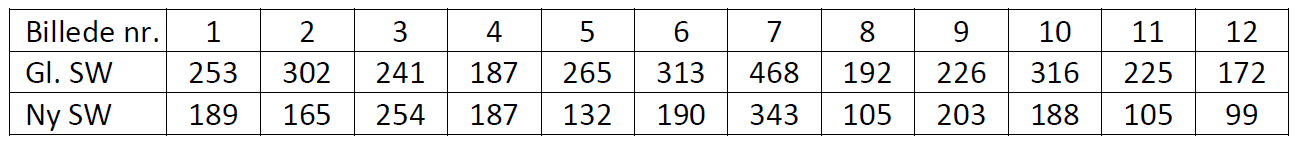

**a) Hvad er den estimerede forbedring af procestiden ved testen?**

    GSW=[253 302 241 187 265 313 468 192 226 316 225 172];
    NSW=[189 165 254 187 132 190 343 105 203 188 105 99];
    
Improvements=GSW-NSW

Improvements =     64   137   -13     0   133   123   125    87    23   128   120    73


samplemean=mean(Improvements)

samplemean = 83.3333

*Den estimerede forbedring er 83.333s*

**b) Hvilken test-statistik skal bruges, for at teste firmaets påstand?**

*Student t-test, grunden bag dette er fordi vi ingen varians har!*

**c) Opstil en NULL hypotese og en alternativ hypotese for testen.**

 H0: $\delta {\;}_0 \;=120s$, den nye software er 2 minutter hurtigere

 H1: $\delta {\;}_0 \;\not= 120s$, den nye software er IKKE 2 minutter hurtigere

delta0=120;

**d) Bestem samplevariansen for testdata.**


$$\mathrm{samplemean}=\;\overline{\;d} =\hat{\;\delta \;} =\frac{1}{n}\sum_{i=1}^n \left(X_{1i} -X_{2i} \right)$$



$${\mathrm{samplevariance}=s}_d^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(X_{1i} -X_{2i} -\overline{\;d} \right)}^2$$


Samplevariance = var(Improvements)

Samplevariance = 2.9413e+03

*Smaplevariansen for det testdataen er 2941.3*

**e) Bestem p-værdien for testen.**


$$t=\frac{\hat{\;\delta \;} -\delta {\;}_0 }{\sqrt{\frac{s_d^2 \;}{n}}}$$


t=(samplemean-delta0)/(sqrt((Samplevariance/length(Improvements))))

t = -2.3420


$$\mathrm{pval}=2\cdot \;\left(1-t_{\mathrm{cdf}} \left(\left|t\right|,n-1\right)\right)$$


p=2*(1-tcdf(abs(t),length(Improvements)-1))

p = 0.0390

**f) Bestem 95% konfidensintervallet for tidsforbedringen.**


$$t_0 =\mathrm{tinv}\left(1-\frac{0\ldotp 05}{2},n-1\right)=\mathrm{tinv}\left(0\ldotp 975,n-1\right)$$


t0=tinv(0.975,length(Improvements)-1)

t0 = 2.2010


$$\Delta \;\delta =t_0 \cdot \sqrt{\frac{s_d^2 }{n}}$$


Delta=t0*sqrt((Samplevariance/length(Improvements)))

Delta = 34.4587

nedre=samplemean-Delta

nedre = 48.8747

ovre=samplemean+Delta

ovre = 117.7920

**g) Lever det nye software op til firmaets påstand med et signifikansniveau på 5%?**

*Da vores pværdi er under 5% kan vi antage at det nye software IKKE er 2 minutter hurtigere*

*Ud fra vores konfidensinterval kan vi se at den som antaget ud fra p-værdien ikke er 2 minutter hurtigere*

*Deres påstand om at softwaren er 2 minutter hurtigere er faktuelt forkert!*

*Vi kan nu forkaste null-hypotesen*